## Construct 3-phase sampled signal

You could either create a synthetic signal or read a sampled signal from a file, then interpolate it for the derivatives:

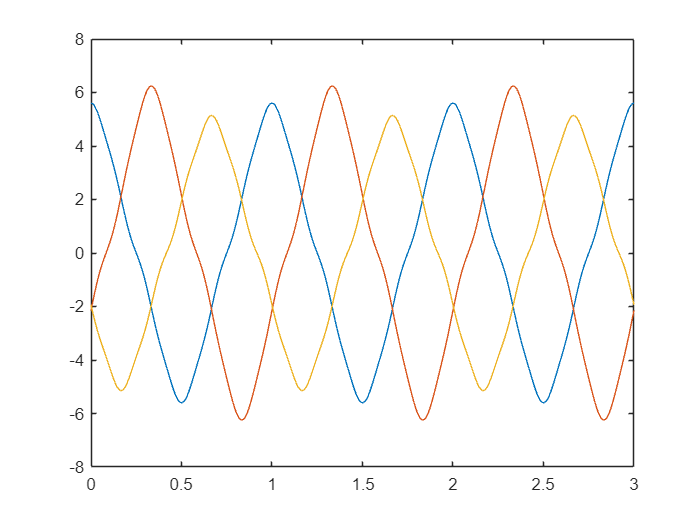

% Fundamental frequency
f = 1;
w = 2 * pi * f;

% Sampled time
t = linspace(0, 3, 1000 * 3 + 1);

% Harmonic Signal components
p = [w * t; w * t - 2 * pi / 3; w * t + 2 * pi / 3];

m = [
    5, 0.5, 0.1; 
    5.5, 0.65, 0.09; 
    4.6, 0.42, 0.12
];

a = m(1,1) * cos(p(1,:)) + m(1,2) * cos(3 * p(1,:)) + m(1,3) * cos(7 * p(1,:));
b = m(2,1) * cos(p(2,:)) + m(2,2) * cos(3 * p(2,:)) + m(2,3) * cos(7 * p(2,:));
c = m(3,1) * cos(p(3,:)) + m(3,2) * cos(3 * p(3,:)) + m(3,3) * cos(7 * p(3,:));

plot(t,a);
hold on;
plot(t,b);
plot(t,c);
hold off;

Define the first derivative:

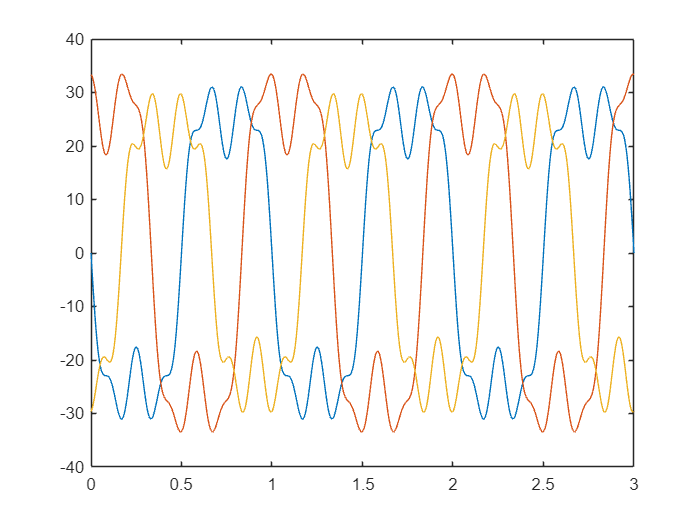

aDt1 = -w * m(1,1) * sin(p(1,:)) - 3 * w * m(1,2) * sin(3 * p(1,:)) - 7 * w * m(1,3) * sin(7 * p(1,:));
bDt1 = -w * m(2,1) * sin(p(2,:)) - 3 * w * m(2,2) * sin(3 * p(2,:)) - 7 * w * m(2,3) * sin(7 * p(2,:));
cDt1 = -w * m(3,1) * sin(p(3,:)) - 3 * w * m(3,2) * sin(3 * p(3,:)) - 7 * w * m(3,3) * sin(7 * p(3,:));

plot(t,aDt1);
hold on;
plot(t,bDt1);
plot(t,cDt1);
hold off;

Define the second derivative:

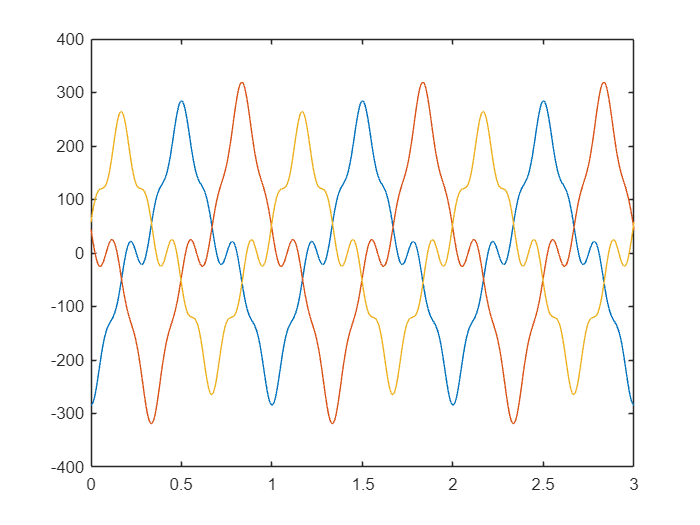

aDt2 = -w * w * m(1,1) * cos(p(1,:)) - 3 * w * w * m(1,2) * cos(3 * p(1,:)) - 7 * w * w * m(1,3) * cos(7 * p(1,:));
bDt2 = -w * w * m(2,1) * cos(p(2,:)) - 3 * w * w * m(2,2) * cos(3 * p(2,:)) - 7 * w * w * m(2,3) * cos(7 * p(2,:));
cDt2 = -w * w * m(3,1) * cos(p(3,:)) - 3 * w * w * m(3,2) * cos(3 * p(3,:)) - 7 * w * w * m(3,3) * cos(7 * p(3,:));

plot(t,aDt2);
hold on;
plot(t,bDt2);
plot(t,cDt2);
hold off;

% Create a singel GA vector for the signal and its derivatives
v = ga3.EncodeVector([a; b; c]);
vDt1 = ga3.EncodeVector([aDt1; bDt1; cDt1]);
vDt2 = ga3.EncodeVector([aDt2; bDt2; cDt2]);

## Calculate Arc-Length Derivatives

Time derivatives of arc-length variable s:

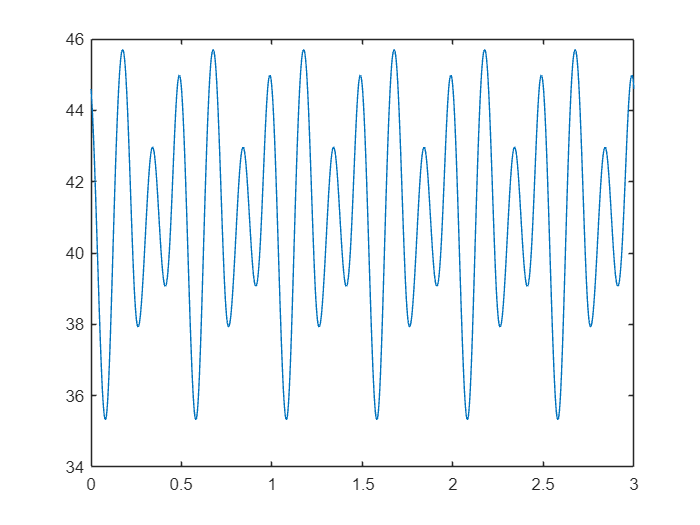

sDt1 = vDt1.norm();
sDt2 = vDt1.sp(vDt2) ./ sDt1;
%sDt3 = (vDt2.sp(vDt2) + vDt1.sp(vDt3) - sDt2.Square()) / sDt1;

plot(t,sDt1);

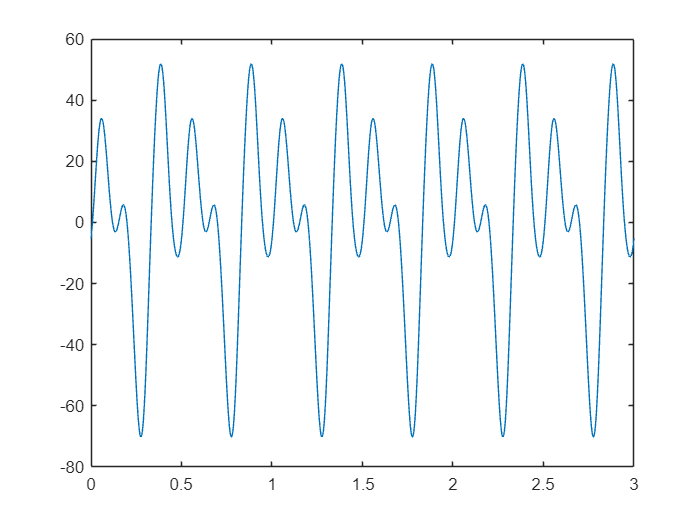

plot(t,sDt2);

%plot(t,sDt3);

Arc-length derivatives of vector signal:

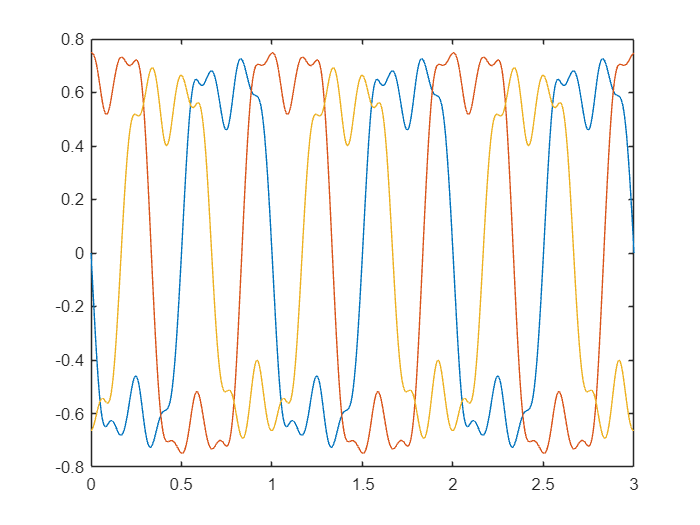

vDs1 = vDt1 / sDt1;
vDs2 = (vDt2 * sDt1 - vDt1 * sDt2) / power(sDt1, 3);
%vDs3 = (power(sDt1, 2) * vDt3 - 3 * sDt1 * sDt2 * vDt2 + (3 * power(sDt2, 2) - sDt1 * sDt3) * vDt1) / power(sDt1, 5);

plot(t, vDs1.Data(1,:));
hold on;
plot(t, vDs1.Data(2,:));
plot(t, vDs1.Data(3,:));
hold off;

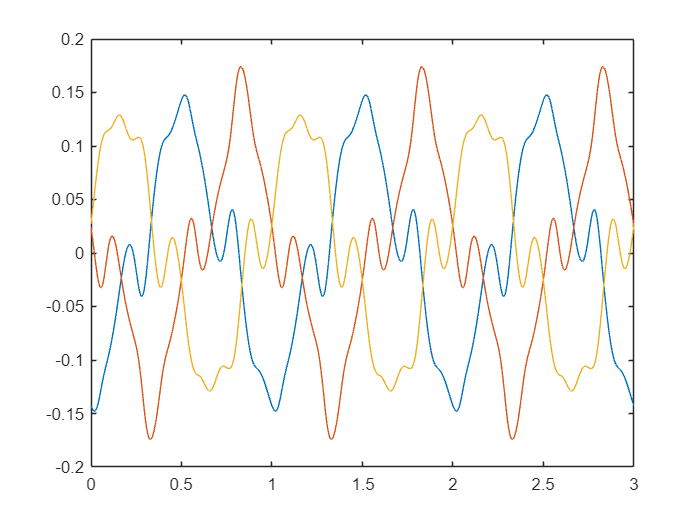


plot(t, vDs2.Data(1,:));
hold on;
plot(t, vDs2.Data(2,:));
plot(t, vDs2.Data(3,:));
hold off;

## Calculate Orthonormal Frames

u1 = vDs1;
u2 = vDs2 - vDs1 * (vDs2.sp(vDs1) ./ vDs1.sp(vDs1));
u3 = vDs1.op(vDs2).dual();
e1 = u1 / u1.norm();
e2 = u2 / u2.norm();
e3 = u3 / u3.norm();

We list the basic operations on a multivector that is expressed either as a sum of k-vectors $A=\sum_{k=0}^{n}\left\langle A\right\rangle _{k}$ or as a sum of basis blades $A=\sum_{i=0}^{2^{n}-1}a_{i}E_{i}$.

## Calculate Curvatures

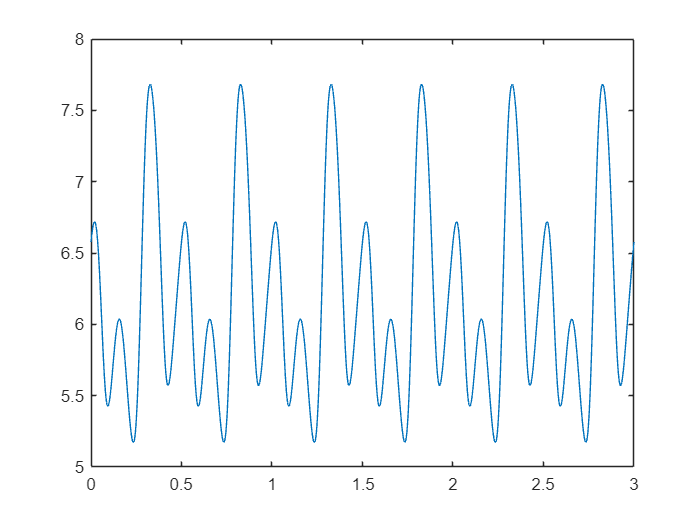

k1 = sDt1 .* u2.norm() ./ u1.norm();
k2 = sDt1 .* u3.norm() ./ u2.norm();
plot(t,k1);

plot(t,k2);

## Calculate Darboux Bivectors

db1 = e1.op(e2) * k1;
db2 = e2.op(e3) * k2;
db = db1 + db2;
plot(t, db1.norm());

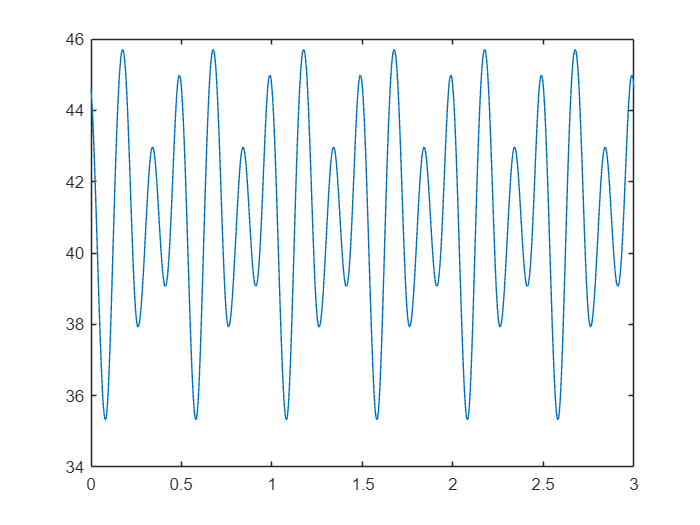

plot(t, db2.norm());

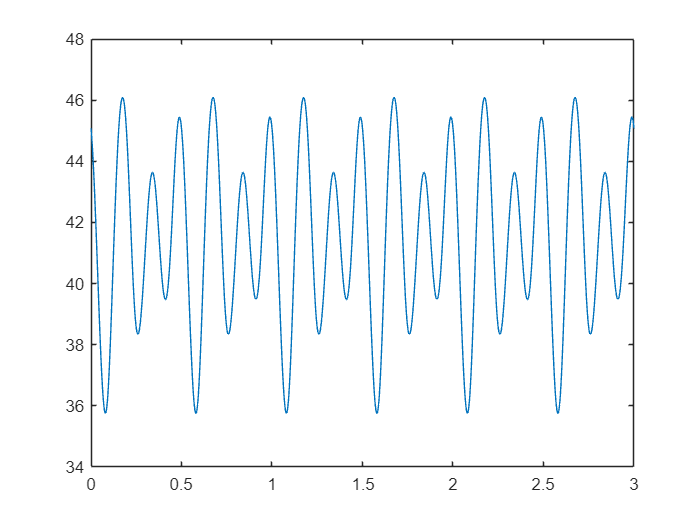

plot(t, db.norm());

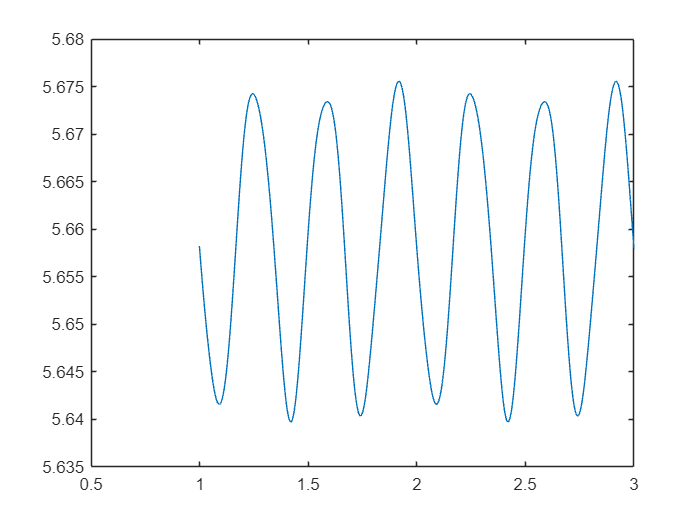

% Plot the norm of the moving mean Darboux bivectors taken over one cycle
% (1000 samples)
dbMean = ga3.Multivector(2,movmean(db.Data,[1000,0],2));
dbMeanNorm = dbMean.norm();
plot(t(1000:end),dbMeanNorm(1000:end));